% Membaca file Excel
dischargeData = readtable('Discharge.xlsx');
chargeData = readtable('Charge.xlsx');

% === STEP 2: EKSTRAK DATA DENGAN NAMA KOLOM YANG BENAR ===
% Untuk Charge.xlsx
time_c = chargeData.Test_Time - chargeData.Test_Time(1);  % waktu relatif dalam detik
current_c = chargeData.Current;
voltage_c = chargeData.Voltage;

% Untuk Discharge.xlsx
time_d = dischargeData.Test_Time - dischargeData.Test_Time(1);
current_d = dischargeData.Current;
voltage_d = dischargeData.Voltage;
time_c = chargeData.Test_Time - chargeData.Test_Time(1);  % dalam detik
current_c = chargeData.Current;
voltage_c = chargeData.Voltage;

time_d = dischargeData.Test_Time - dischargeData.Test_Time(1);
current_d = dischargeData.Current;
voltage_d = dischargeData.Voltage;

% === STEP 3: HITUNG SoC DENGAN COULOMB COUNTING ===
Q_nom = 1.1 * 3600;  % kapasitas nominal baterai dalam Coulomb

% CHARGE
dt_c = diff(time_c);                    
I_c = current_c(1:end-1);              
deltaQ_c = I_c .* dt_c;                
cumQ_c = cumsum(deltaQ_c);             
soc_c = cumQ_c / Q_nom;                
soc_c(end+1) = soc_c(end);             
soc_c = max(min(soc_c,1),0);           

% DISCHARGE (SoC dari 1 ke 0)
dt_d = diff(time_d);
I_d = abs(current_d(1:end-1));          % gunakan nilai mutlak arus
deltaQ_d = I_d .* dt_d;
cumQ_d = cumsum(deltaQ_d);
soc_d = 1 - cumQ_d / Q_nom;
soc_d(end+1) = soc_d(end);
soc_d = max(min(soc_d,1),0);

% === STEP 3b: SIMPAN SoC MENTAH UNTUK PLOT RAW ===========================
soc_c_raw = soc_c;      % charge  (belum dinormalisasi: 0 → ~1)
soc_d_raw = soc_d;      % discharge (belum dinormalisasi: ~1 → 0)

% === NORMALISASI SoC DENGAN RESCALING ===

% --- CHARGE (SoC dari 0 ke 1) ---
soc_c = soc_c - soc_c(1);  % pastikan mulai dari 0
soc_c = soc_c / (soc_c(end));  % normalisasi agar akhir = 1

% --- DISCHARGE (SoC dari 1 ke 0) ---
soc_d = soc_d - soc_d(end);  % pastikan akhir = 0
soc_d = soc_d / (soc_d(1));  % normalisasi agar awal = 1

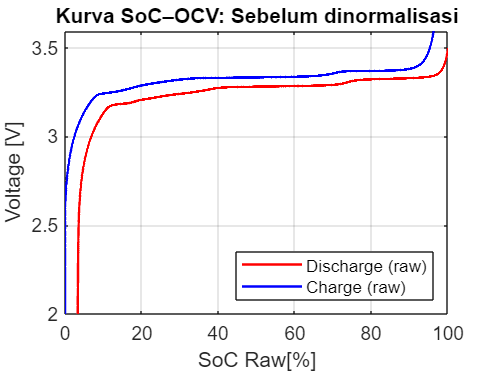

% === PLOT SoC–VOLTAGE MENTAH (TIDAK DINORMALISASI) =======================
figure;
plot(soc_d_raw*100, voltage_d(1:length(soc_d_raw)), 'r-', 'LineWidth', 1.2); hold on;
plot(soc_c_raw*100, voltage_c(1:length(soc_c_raw)), 'b-', 'LineWidth', 1.2);
xlabel('SoC Raw[%]');
ylabel('Voltage [V]');
title('Kurva SoC–OCV: Sebelum dinormalisasi');
legend('Discharge (raw)', 'Charge (raw)', 'Location', 'southeast');
grid on;

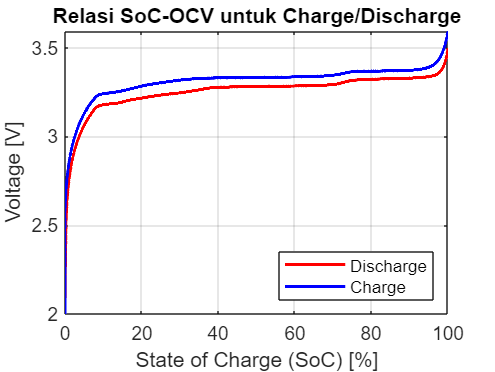

% === STEP 4: PLOT GRAFIK ===
figure;
plot(soc_d*100, voltage_d(1:length(soc_d)), 'r-', 'LineWidth', 1.5); hold on;
plot(soc_c*100, voltage_c(1:length(soc_c)), 'b-', 'LineWidth', 1.5);
xlabel('State of Charge (SoC) [%]');
ylabel('Voltage [V]');
title('Relasi SoC-OCV untuk Charge/Discharge');
legend('Discharge', 'Charge', 'Location', 'southeast');
grid on;

% === STEP 5: INTERPOLASI DAN PERATAAN (OCV Curve) ===

% Buat grid SoC dari 0 ke 1 (misal 101 titik, tiap 1%)
soc_grid = linspace(0, 1, 101);  % SoC 0%–100%

% Hapus duplikasi pada SoC dan ambil tegangan unik untuk interpolasi
[soc_c_unique, ia_c] = unique(soc_c);
voltage_c_unique = voltage_c(ia_c);

[soc_d_unique, ia_d] = unique(soc_d);
voltage_d_unique = voltage_d(ia_d);

% Interpolasi tegangan terhadap SoC grid
v_charge_interp = interp1(soc_c_unique, voltage_c_unique, soc_grid, 'linear', 'extrap');
v_discharge_interp = interp1(soc_d_unique, voltage_d_unique, soc_grid, 'linear', 'extrap');

% Rata-rata tegangan charge dan discharge → kurva OCV utama
v_avg = (v_charge_interp + v_discharge_interp) / 2;

% === STEP 6: FITTING POLINOMIAL ===
poly_order = 8  ;  % bisa disesuaikan (5–7 umum dipakai)
coeffs = polyfit(soc_grid, v_avg, poly_order);  % fitting OCV curve
v_fit = polyval(coeffs, soc_grid);  % hasil evaluasi fitting

disp('Koefisien polynomial:');

Koefisien polynomial:


disp(coeffs);  % dari pangkat tertinggi ke terendah

   1.0e+03 *

   -1.0979    4.9095   -9.0725    8.9523   -5.0861    1.6719   -0.3033    0.0272    0.0023




% Contoh bentuk fungsi:
% OCV(SoC) = coeffs(1)*SoC^5 + coeffs(2)*SoC^4 + ... + coeffs(6)

% === EVALUASI EROR FITTING POLINOMIAL ====================================
rmse_poly = sqrt(mean((v_fit - v_avg).^2));          % RMSE
mae_poly  = mean(abs(v_fit - v_avg));                % MAE (opsional)

fprintf('RMSE polynomial vs OCV rata-rata  : %.4f V\n', rmse_poly);

RMSE polynomial vs OCV rata-rata  : 0.0482 V


fprintf('MAE  polynomial vs OCV rata-rata  : %.4f V\n', mae_poly);

MAE  polynomial vs OCV rata-rata  : 0.0251 V


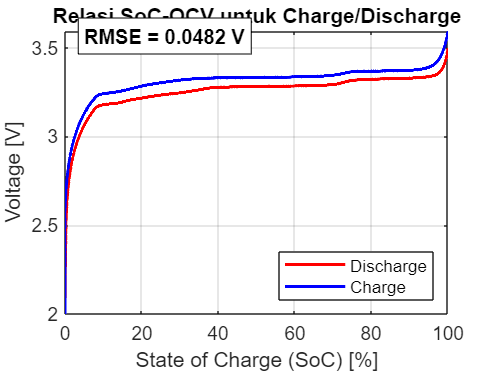


% (opsional) tulis RMSE pada plot akhir
figure(gcf);                                         % pastikan masih di figur STEP 7
txt = sprintf('RMSE = %.4f V', rmse_poly);
xpos = 5; ypos = max(v_avg)+0.02;                    % letak label
text(xpos, ypos, txt, 'FontSize', 10, 'FontWeight', 'bold', ...
     'BackgroundColor',[1 1 1 0.6], 'EdgeColor',[0 0 0 0.2]);

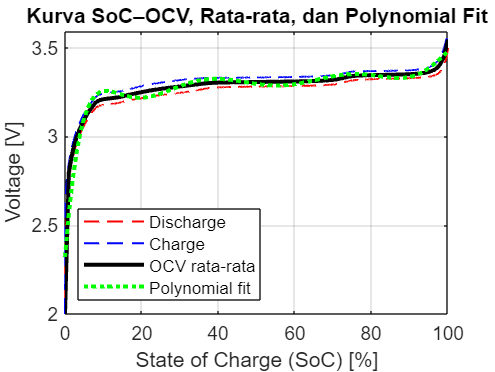

% === STEP 7: PLOT FINAL ===
figure;
plot(soc_d(1:length(voltage_d))*100, voltage_d, 'r--', 'LineWidth', 1); hold on;
plot(soc_c(1:length(voltage_c))*100, voltage_c, 'b--', 'LineWidth', 1);
plot(soc_grid*100, v_avg, 'k-', 'LineWidth', 2);     % kurva OCV utama
plot(soc_grid*100, v_fit, 'g:', 'LineWidth', 2);     % hasil fitting

xlabel('State of Charge (SoC) [%]');
ylabel('Voltage [V]');
title('Kurva SoC–OCV, Rata-rata, dan Polynomial Fit');
legend('Discharge', 'Charge', 'OCV rata-rata', 'Polynomial fit', 'Location', 'southwest');
grid on;

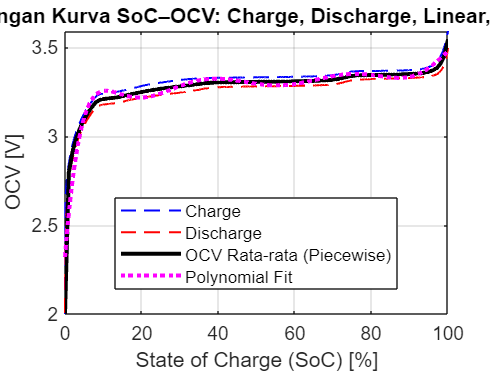

% === STEP 8: PERBANDINGAN CHARGE, DISCHARGE, OCV LINEAR, DAN POLYNOMIAL ===

% SoC untuk evaluasi kurva
soc_test = linspace(0, 1, 1000);

% Interpolasi semua kurva
v_charge_test     = interp1(soc_c_unique, voltage_c_unique, soc_test, 'linear', 'extrap');
v_discharge_test  = interp1(soc_d_unique, voltage_d_unique, soc_test, 'linear', 'extrap');
v_linear_avg      = interp1(soc_grid, v_avg, soc_test, 'linear');  % OCV rata-rata (piecewise linear)
v_poly_fit        = polyval(coeffs, soc_test);                     % Polynomial fit

% Plot semua
figure;
plot(soc_test*100, v_charge_test, 'b--', 'LineWidth', 1); hold on;
plot(soc_test*100, v_discharge_test, 'r--', 'LineWidth', 1);
plot(soc_test*100, v_linear_avg, 'k-', 'LineWidth', 2);
plot(soc_test*100, v_poly_fit, 'm:', 'LineWidth', 2);

xlabel('State of Charge (SoC) [%]');
ylabel('OCV [V]');
title('Perbandingan Kurva SoC–OCV: Charge, Discharge, Linear, Polynomial');
legend('Charge', 'Discharge', 'OCV Rata-rata (Piecewise)', 'Polynomial Fit', 'Location', 'best');
grid on;